# UMAP paper code 2

### Import PCA

Areas = ["1","3b","VPL"];
cd("../../../../../../../../../../../../../../home/bernardo/Desktop/Paper_sebas/Datos/Datos Sergio")

cd("pca_sorting/")

N_PCA = 63 + 14 +68;
n = 0;
Neu_PCA = cell(N_PCA,1);
for a = Areas
    cd(a)
    Files = dir("*.*");
    Files = Files(3:end);
    for file = 1:length(Files)
        n = n + 1;
        S = load(Files(file).name);
        Neu_PCA{n} = S.single;
    end
    cd("../")
end

### Import UMAP

cd("../../../../../../../../../../../../../../home/bernardo/Desktop/Paper_sebas/Datos/Datos Sergio")

cd("toposort_sorting/")

N_UMAP = 140 + 45 + 180;
n = 0;
Neu_UMAP = cell(N_UMAP,1);
for a = Areas
    cd(a)
    Files = dir("*.*");
    Files = Files(3:end);
    for file = 1:length(Files)
        n = n + 1;
        S = load(Files(file).name);
        Neu_UMAP{n} = S.single;
    end
    cd("../")
end

## N session by session

Rec_day = [""];
d = 0;
for n = 1:N_PCA
    if ~ismember(Rec_day,Neu_PCA{n}.session)
        d = d + 1;
        Rec_day(d) = Neu_PCA{n}.session;
    end
end

N_methods = zeros(length(Rec_day),2,2);
for a = 1:2
    if a == 1 %Area 1 or 3b
        for d = 1:length(Rec_day)
            for n = 1:N_PCA
                N_methods(d,1,a) = N_methods(d,1,a) + ...
                    (Neu_PCA{n}.session == Rec_day(d) & ismember(Neu_PCA{n}.ReceptiveField_i,[1,2]) & ...
                    ismember(Neu_PCA{n}.Area_i,Areas(1:2)));
            end
            for n = 1:N_UMAP
                N_methods(d,2,a) = N_methods(d,2,a) + ...
                    (Neu_UMAP{n}.session == Rec_day(d) & ismember(Neu_UMAP{n}.ReceptiveField_i,[1,2]) & ...
                    ismember(Neu_UMAP{n}.Area_i,Areas(1:2)));
            end
        end
    else %VPL
        for d = 1:length(Rec_day)
            for n = 1:N_PCA
                N_methods(d,1,a) = N_methods(d,1,a) + ...
                    (Neu_PCA{n}.session == Rec_day(d) & ismember(Neu_PCA{n}.ReceptiveField_i,[1,2]) & ...
                    ismember(Neu_PCA{n}.Area_i,Areas(3)));
            end
            for n = 1:N_UMAP
                N_methods(d,2,a) = N_methods(d,2,a) + ...
                    (Neu_UMAP{n}.session == Rec_day(d) & ismember(Neu_UMAP{n}.ReceptiveField_i,[1,2]) & ...
                    ismember(Neu_UMAP{n}.Area_i,Areas(3)));
            end
        end
    end
end

Discard days with no neurons for areas 1 and 3b

for a = 1:2
    for d = 1:length(Rec_day)
        if N_methods(d,1,a) == 0 && N_methods(d,2,a) == 0
            N_methods(d,1:2,a) = [nan,nan];
        end
    end
end

Plot

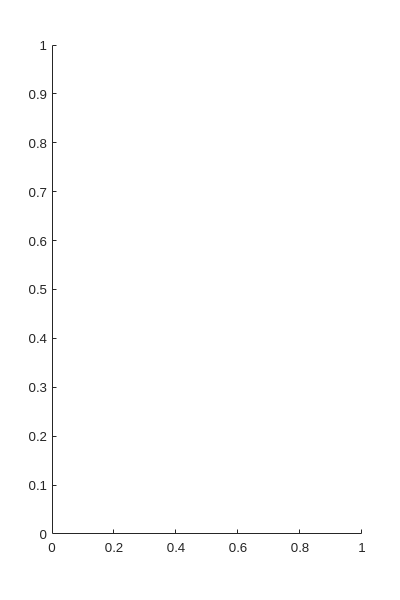

a = 2;
clf, hold off

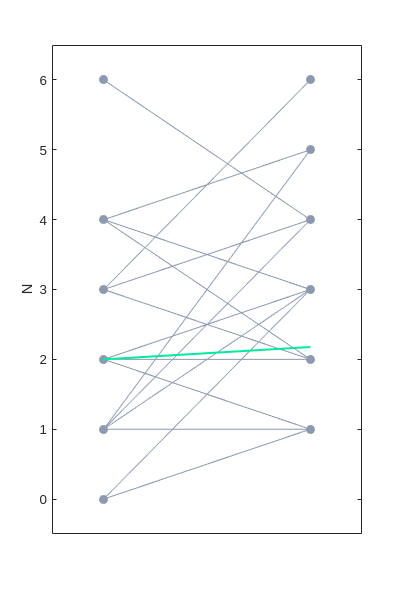

figure('Renderer', 'painters', 'Position', [10 10 400 600])
plot(N_methods(:,:,a).',Color="#8d99ae",Marker=".",MarkerSize=20)
hold on
plot(mean(squeeze(N_methods(:,:,a)),"omitnan"),Color="#00EAA0",LineWidth=1.5)
ylabel("N")
xlim([0.75,2.25])
ylim([-0.5,6.5])
xticklabels([])
xticks([])
%saveas(gcf, "N_VPL.svg")

T-value

N_methods1 = squeeze(N_methods(:,:,a));
[~,~,~,stats] = ttest(N_methods1(:,1),N_methods1(:,2));
Ttrue = stats.tstat

Ttrue = -0.6828


Tperm = zeros(1,1000);
Np = [N_methods1(:,1),N_methods1(:,2)];
for p = 1:1000
    Np = Np(randperm(length(Np)));
    [~,~,~,stats] = ttest(Np(1:length(Rec_day)),N_methods1(length(Rec_day) + 1:end));
    Tperm(p) = stats.tstat;
end

pvalue = sum(abs(Tperm) > abs(Ttrue))/1000

pvalue = 0.0340

## Mutual Information

### Firing rate

Binary to time

for n = 1:N_PCA
    Neu_PCA{n}.zo.neu_i(Neu_PCA{n}.zo.neu_i == -1) = 0; %Delete -1's
    Neu_PCA{n}.zo.neu_time = bin2tim(Neu_PCA{n}.zo.neu_i);
end
for n = 1:N_UMAP
   Neu_UMAP{n}.zo.neu_i(Neu_UMAP{n}.zo.neu_i == -1) = 0;
   Neu_UMAP{n}.zo.neu_time = bin2tim(Neu_UMAP{n}.zo.neu_i);
end

Align times

for n = 1:N_PCA
    Neu_PCA{n}.zo.neu_time = Neu_PCA{n}.zo.neu_time - Neu_PCA{n}.TimesEvents(:,3);
end
for n = 1:N_UMAP
   Neu_UMAP{n}.zo.neu_time = Neu_UMAP{n}.zo.neu_time - Neu_UMAP{n}.TimesEvents(:,3);
end

Fr

mini = -4; maxi = 5; pas = 0.02; win = 0.1;
tv = mini:pas:maxi;
lentv = length(tv);

Fr_PCA = cell(N_PCA, 1);
for n = 1:N_PCA
    Fr_PCA{n} = freq(Neu_PCA{n}.zo.neu_time(Neu_PCA{n}.StimAmpHitStimOnSet(:,5) == 1,:), ...
        pas, win, mini, maxi);
end


Fr_UMAP = cell(N_UMAP, 1);
for n = 1:N_UMAP
    try
        Fr_UMAP{n} = freq(Neu_UMAP{n}.zo.neu_time(Neu_UMAP{n}.StimAmpHitStimOnSet(:,5) == 1,:), ...
        pas, win, mini, maxi);
    catch
        n
    end
end

Psyhits

Psyhit_PCA = cell(length(Rec_day),1);
for n = 1:N_PCA
    Psyhit_PCA{n}.AmpStim3 = Neu_PCA{n}.StimAmpHitStimOnSet(Neu_PCA{n}.StimAmpHitStimOnSet(:,5) == 1,4);
end

Psyhit_UMAP = cell(length(Rec_day),1);
for n = 1:N_UMAP
    Psyhit_UMAP{n}.AmpStim3 = Neu_UMAP{n}.StimAmpHitStimOnSet(Neu_UMAP{n}.StimAmpHitStimOnSet(:,5) == 1,4);
end

UMAP Receptive field 1 or 2

RF_UMAP = zeros(N_UMAP,1);
for n = 1:N
    if ismember(Neu_UMAP{n}.ReceptiveField_i,[1,2])
        RF_UMAP(n) = 1;
    end
end
RF_UMAP = logical(RF_UMAP);

PCA 

N = 140;
Fr = Fr_PCA;
Psyhit = Psyhit_PCA;
pi = 1:N;

then UMAP

N = N_UMAP;  %140;
Fr = Fr_UMAP;
Psyhit = Psyhit_UMAP;
pi = 1:N;

meanClass = cell(N,1);
classes = unique(Neu_PCA{1}.StimAmpHitStimOnSet(:,4));
C = length(classes); %number of classes

for n = 1:N
    meanClass{n} = zeros(C,lentv);
    for c = 1:C
        meanClass{n}(c,:) = mean(Fr{n}(Psyhit{pi(n)}.AmpStim3 == classes(c), :), 1);
    end
end

Ploting

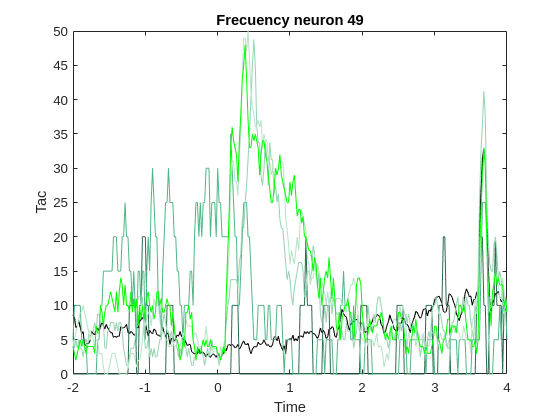

coltac = ["#081c15", "#2d6a4f", "#52b788", "#95d5b2", "#b7e4c7", "g"];

n = 49;

clf, hold off
plot(tv, meanClass{n}(1,:), "Color", "k")
hold on
for c = 2:7
    plot(tv, meanClass{n}(c,:), "Color", coltac(c-1))
end
ylabel("Tac"), xlabel("Time")
xlim([-2,4])
title(strcat("Frecuency neuron ", num2str(n)))

### Mutual Information

ii = 200; i = tv(ii); e = tv(250); %ii = 100; e = tv(400);
wind = tv >= i & tv <= e;
lenwin = sum(wind);
Ps = [1/2, 1/2]; IM_UMAP = zeros(N,lenwin); %IM_PCA = zeros(N,lenwin);


for n = 1:N
    for t1 = 1: lenwin
        t = t1 + ii - 1;
        ed = linspace(min(Fr{n}(:,t),[],"all"),max(Fr{n}(:,t),[],"all"),10);
        Pt = histcounts(Fr{n}(:,t),ed,"Normalization","probability");
        
        Psr1 = histcounts(Fr{n}(Psyhit{pi(n)}.AmpStim3 ~= 0.,t), ... 
            ed,"Normalization","probability");
        Psr2 = histcounts(Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0.,t), ...
            ed,"Normalization","probability");
        IM_UMAP(n,t1) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan");        
    end
end

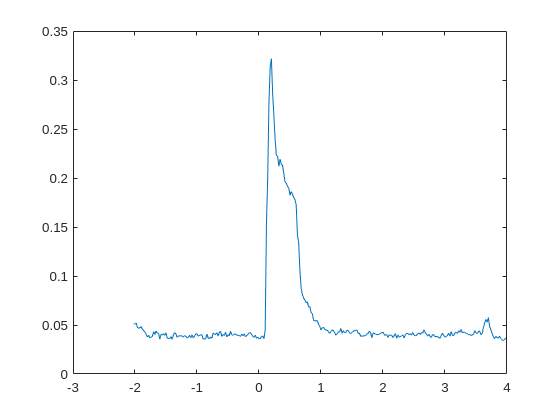

clf, hold off
plot(tv(wind),mean(IM_UMAP(RF_UMAP,:)))

#### Permutations

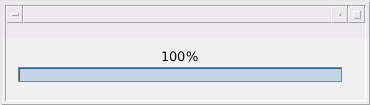

IMp_UMAP = zeros(N,lenwin, 1000); %IMp_PCA = zeros(N,lenwin, 1000);

wb = waitbar(0);
for n = 1:N
    waitbar(n/N, wb, strcat(num2str(round(n/N*100,2)),"%"))
    if RF_UMAP(n) == 1
    for t1 = 1:lenwin
        t = t1 + ii - 1;
        ed = linspace(min(Fr{n}(:,t),[],"all"),max(Fr{n}(:,t),[],"all"),10);
        Pt = histcounts(Fr{n}(:,t),ed,"Normalization","probability");
        Frp = Fr{n}(:,t);

        for p = 1:1000
        Frp = Frp(randperm(length(Frp)));

        Psr1 = histcounts(Frp(Psyhit{pi(n)}.AmpStim3 ~= 0.), ...
            ed,"Normalization","probability");
        Psr2 = histcounts(Frp(Psyhit{pi(n)}.AmpStim3 == 0.), ...
            ed,"Normalization","probability");
        IMp_UMAP(n,t1,p) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan");
        end
    end
    end
end

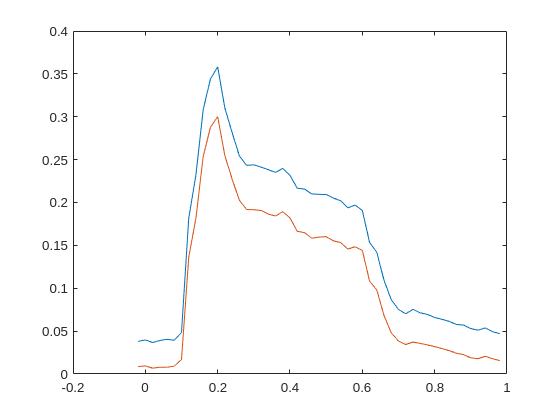

IMr_PCA = IM_PCA - mean(IMp_PCA,3);
IMr_PCA(IMr_PCA < 0) = 0;

clf, hold off
plot(tv(wind),mean(IM_PCA))
hold on
plot(tv(wind),mean(IMr_PCA))

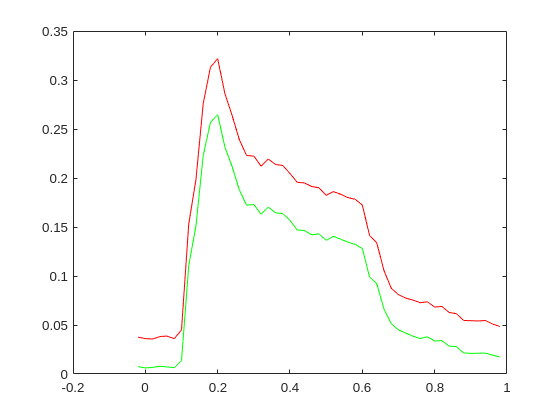

IMr_UMAP = IM_UMAP(RF_UMAP,:) - mean(IMp_UMAP(RF_UMAP,:,:),3);
IMr_UMAP(IMr_UMAP < 0) = 0;

clf, hold off
plot(tv(wind),mean(IM_UMAP(RF_UMAP,:)),color="r")
hold on
plot(tv(wind),mean(IMr_UMAP),color="g")

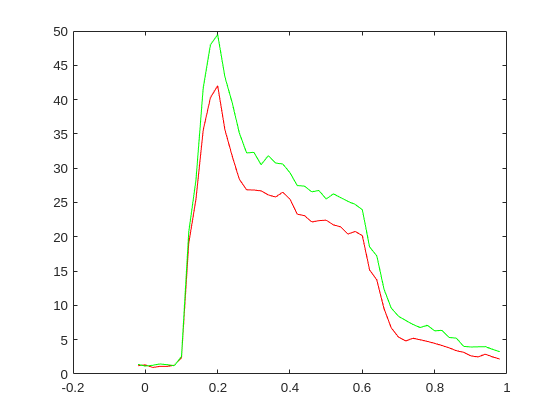

clf, hold off
plot(tv(wind),sum(IMr_PCA),color="r")
hold on
plot(tv(wind),sum(IMr_UMAP),color="g")

#### Electrode MI

El_names_PCA = which_el(Neu_PCA,N_PCA);
El_names_PCA = El_names_PCA(1:140); 

El_names_UMAPf = which_el(Neu_UMAP,N_UMAP);
El_names_UMAP = El_names_UMAPf(RF_UMAP);

N_el = length(unique(El_names_UMAP));
El = [[unique(El_names_PCA),NaN(1,N_el - length(unique(El_names_PCA)))];
    unique(El_names_UMAP); NaN(1,N_el)];

%IM per electrode
IMel = zeros(N_el,2);
for el = 1:N_el
    IMel(el,1) = sum(mean(IMr_PCA(El_names_PCA == El(2,el),:),2));
    IMel(el,2) = sum(mean(IMr_UMAP(El_names_UMAP == El(2,el),:),2));
end
IMel(isnan(IMel)) = 0;
plus = IMel(:,1) + IMel(:,2);
minus = IMel(:,2) - IMel(:,1);

%areas
for el = 1:N_el
    a = 0;
    for n = 1:N_UMAP
        if El_names_UMAPf(n) == El(2,el)
            if a == 1 && Neu_UMAP{n}.Area_i ~= El(3,el) %check if all names congruent
                n
            end
            a = 1;
            El(3,el) = Neu_UMAP{n}.Area_i;
        end
    end
end

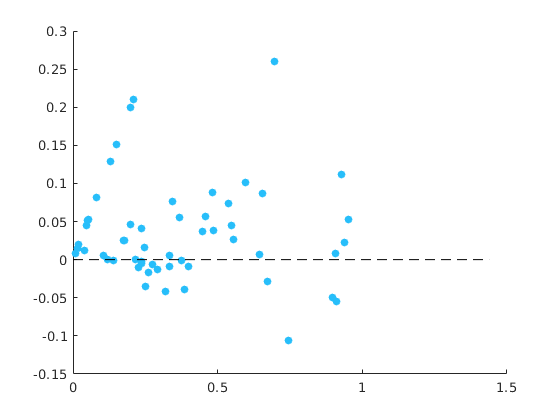

clf, hold off
scatter(plus(ismember(El(3,:),Areas(1:2))),minus(ismember(El(3,:),Areas(1:2))), ...
    MarkerFaceColor="#27BEFA",MarkerEdgeColor="none")
hold on
plot([0,max(plus)],[0,0],LineStyle="--",Color="k")
saveas(gcf, "IMe_S1.svg")

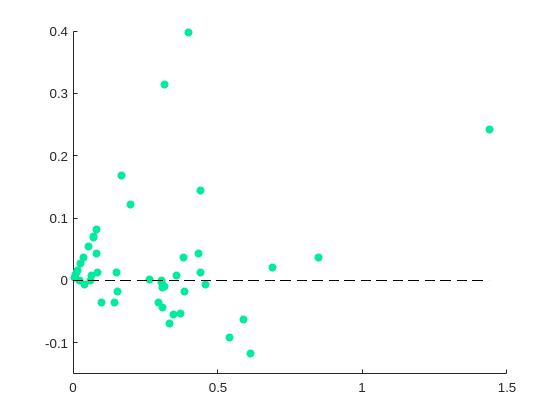

clf, hold off
scatter(plus(ismember(El(3,:),Areas(3))),minus(ismember(El(3,:),Areas(3))), ...
    MarkerFaceColor="#00EAA0",MarkerEdgeColor="none")
hold on
plot([0,max(plus)],[0,0],LineStyle="--",Color="k")
ylim([-0.15,0.4])
saveas(gcf, "IMe_VPC.svg")

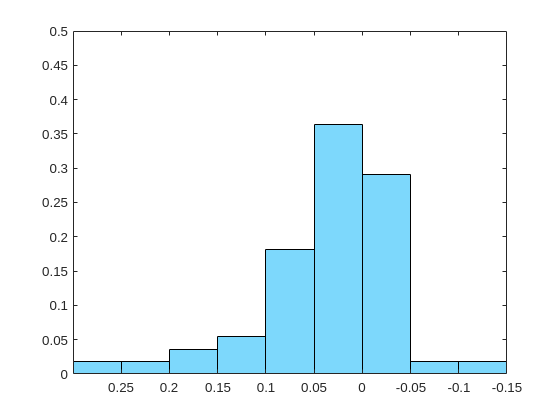

clf, hold off
histogram(minus(ismember(El(3,:),Areas(1:2))),FaceColor="#27BEFA",Normalization="probability",BinEdges=-0.15:0.05:0.3)
xlim([-0.15,0.3])
ylim([0,0.5])
set(gca, 'XDir','reverse')
saveas(gcf, "IMehist_S1.svg")

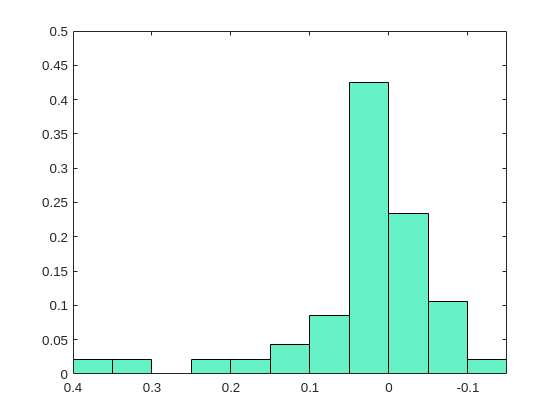

clf, hold off
histogram(minus(ismember(El(3,:),Areas(3))),FaceColor="#00EAA0",Normalization="probability",BinEdges=-0.15:0.05:0.4)
xlim([-0.15,0.4])
ylim([0,0.5])
set(gca, 'XDir','reverse')
saveas(gcf, "IMehist_VPL.svg")

function Tm = bin2tim(bin)
    [xd, yd] = size(bin);
    Tm = nan(xd,max(sum(bin,2)));
    for x = 1:xd
        i = 1;
        for y = 1:yd
            if bin(x,y) == 1
                Tm(x,i) = (y-1)*0.001;
                i = i + 1;
            end
        end
    end
end
    
function Fr = freq(D,pas,ven, mini, maxi)
    [xd, ~] = size(D);
    num = fix(ven/pas);
    tv = mini:pas:maxi;
    D = fix((D-mini)/pas)+1;
    Fr = zeros(xd,length(tv));
    for ens = 1 : xd
        for x = 1 : (length(tv)-num)
            B = (D(ens,:)>x-num & D(ens,:)<=x);
            suma = sum(B(:));
            Fr(ens,x+num) = suma/ven;
        end
    end
end

function El_names = which_el(Neu,N)
    El_names = string(N);
    for n = 1:N
        El_names(n) = strcat(Neu{n}.session,"_",num2str(Neu{n}.electrode_i));
    end
end